# Presentación Final: Cinemática Diferencial de Piernas

**Paola Rojas Domínguez A01737136**

Enlace a la presentación: [https://www.canva.com/design/DAGpKoLqmOQ/EMkvYyBAB71ClCFKTloSbA/edit?utm_content=DAGpKoLqmOQ&utm_campaign=designshare&utm_medium=link2&utm_source=sharebutton](https://www.canva.com/design/DAGpKoLqmOQ/EMkvYyBAB71ClCFKTloSbA/edit?utm_content=DAGpKoLqmOQ&utm_campaign=designshare&utm_medium=link2&utm_source=sharebutton)

Este script utiliza el toolbox de robótica de Peter Corke para realizar una animación paso a paso de transformaciones homogéneas encadenadas en 3D.

## Inicialización

Se inicia limpiando la consola y la memoria para evitar conflictos de datos anteriores.

clear all
close all
clc

## Ejercicio 1

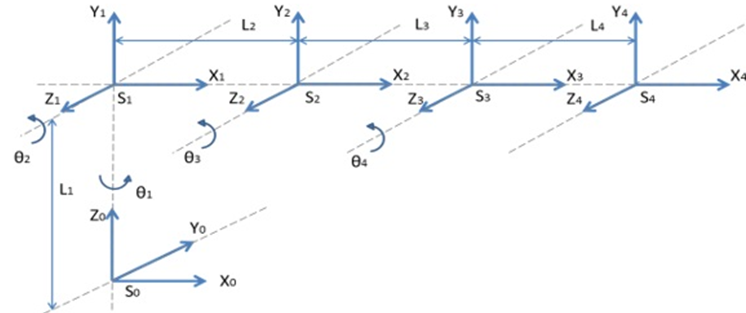

### Modelo cinemático

#### Declaración de Variables

Se declaran las variables simbólicas, esenciales para realizar cálculos simbólicos y analíticos.

syms th1(t) th2(t) th3(t) th4(t) t L1 L2 L3 L4

Se configura el robot con cuatro articulaciones rotacionales, representando su tipo con un vector donde 0 es rotacional y 1 prismático

RP=[0 0 0 0];

Creamos el vector de coordenadas generalizadas

Q= [th1, th2, th3, th4,];
disp('Coordenadas generalizadas'); pretty (Q);

Coordenadas generalizadas
(th1(t), th2(t), th3(t), th4(t))



Creamos el vector de velocidades generalizadas.

Qp= diff(Q, t);
disp('Velocidades generalizadas'); pretty (Qp);

Velocidades generalizadas
/  d          d          d          d        \
| -- th1(t), -- th2(t), -- th3(t), -- th4(t) |
\ dt         dt         dt         dt        /



Posteriormente, definimos los grados de libertad (GDL), es decir, el número de parámetros independientes que definen la posición del extremo del robot, en este caso 4 GDL.

GDL= size(RP,2);
GDL_str= num2str(GDL);
P = sym(zeros(3, 1, GDL));

#### Cinemática Directa

La cinemática directa permite encontrar la posición del extremo del robot a partir de sus ángulos articulares. Para ello, se definen los vectores posición (indican la posición relativa de una articulación) y las matrices de rotación (describen la orientación de un sistema de coordenadas respecto a otro) para cada articulación.

**Articulación 1**


$$R_z \left(\theta \right)\left\lbrack \begin{array}{ccc}
\cos \theta  & -\textrm{sen}\theta  & 0\\
\textrm{sen}\theta  & \cos \theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \times R_x \left(90\right)\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 0 & -1\\
0 & 1 & 0
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
\cos \left(\theta \right) & 0 & \textrm{sen}\left(\theta \right)\\
\textrm{sen}\left(\theta \right) & 0 & -\cos \left(\theta \right)\\
0 & 1 & 0
\end{array}\right\rbrack$$


%Articulación 0 a Articulación 1
%Posición de la articulación 0 a 1
P(:,:,1)= [L1*cos(th1); L1*sin(th1);0];

%Matriz de rotación de la junta 0 a 1
R(:,:,1)= [cos(th1)  0   sin(th1) ;
           sin(th1)  0  -cos(th1) ;
           0         1   0];

**Articulación 2**

No se presenta ningún cambio en los ejes


$$R_z \left(\theta \right)\left\lbrack \begin{array}{ccc}
\cos \theta  & -\textrm{sen}\theta  & 0\\
\textrm{sen}\theta  & \cos \theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$


%Articulación 1 a Articulación 2
%Posición de la articulación 1 a 2
P(:,:,2)= [L2;0;0];

%Matriz de rotación de la junta 1 a 2
R(:,:,2)= [cos(th2)  -sin(th2)   0 ;
           sin(th2)   cos(th2)   0 ;
           0          0          1];

**Articulación 3**

No se presenta ningún cambio en los ejes


$$R_z \left(\theta \right)\left\lbrack \begin{array}{ccc}
\cos \theta  & -\textrm{sen}\theta  & 0\\
\textrm{sen}\theta  & \cos \theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$


%Articulación 2 a Articulación 3
%Posición de la articulación 2 a 3
P(:,:,3)= [L3;0;0];

%Matriz de rotación de la junta 2 a 3
R(:,:,3)= [cos(th3)  -sin(th3)   0 ;
           sin(th3)   cos(th3)   0 ;
           0          0          1];

**Articulación 4**

No se presenta ningún cambio en los ejes


$$R_z \left(\theta \right)\left\lbrack \begin{array}{ccc}
\cos \theta  & -\textrm{sen}\theta  & 0\\
\textrm{sen}\theta  & \cos \theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$


%Articulación 3 a Articulación 4
%Posición de la articulación 3 a 4
P(:,:,4)= [L4;0;0];

%Matriz de rotación de la junta 3 a 4
R(:,:,4)= [cos(th4)  -sin(th4)   0 ;
           sin(th4)   cos(th4)   0 ;
           0          0          1];

Las matrices de transformación homogénea, combinan la rotación y traslación en un solo modelo matemático. Se construyen las matrices locales y globales de transformación para obtener la posición y orientación del extremo del robot en el sistema de referencia inercial.

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL);

%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 

El bucle `for` recorre cada articulación del robot para calcular sus matrices de transformación homogénea locales y globales. Primero, genera la matriz de transformación local, que describe la posición y orientación de la articulación en relación con la anterior. Luego, obtiene la matriz de transformación global, que representa la posición y orientación en el sistema de referencia inercial, acumulando las transformaciones previas. Finalmente, extrae la matriz de rotación y el vector de posición, fundamentales para la cinemática directa y el cálculo del Jacobiano.

for i = 1:GDL
    i_str= num2str(i);

    %Locales
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    disp(strcat('Matriz de Transformación local A', i_str)); pretty(A(:,:,i));
    disp('    ');

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    T(:,:,i)= simplify(T(:,:,i));
    disp(strcat('Matriz de Transformación global T', i_str)); pretty(T(:,:,i));
    disp('    ');

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end

Matriz de Transformación local A1
/ cos(th1(t)), 0,  sin(th1(t)), L1 cos(th1(t)) \
|                                              |
| sin(th1(t)), 0, -cos(th1(t)), L1 sin(th1(t)) |
|                                              |
|      0,      1,       0,             0       |
|                                              |
\      0,      0,       0,             1       /



Matriz de Transformación global T1
/ cos(th1(t)), 0,  sin(th1(t)), L1 cos(th1(t)) \
|                                              |
| sin(th1(t)), 0, -cos(th1(t)), L1 sin(th1(t)) |
|                                              |
|      0,      1,       0,             0       |
|                                              |
\      0,      0,       0,             1       /



Matriz de Transformación local A2
/ cos(th2(t)), -sin(th2(t)), 0, L2 \
|                                  |
| sin(th2(t)),  cos(th2(t)), 0,  0 |
|                                  |
|      0,            0,      1,  0 |
|                                  |
\      0,            0,      0,  1 /



Matriz de Transformación global T2
/ cos(th1(t)) cos(th2(t)), -cos(th1(t)) sin(th2(t)),  sin(th1(t)), cos(th1(t)) (L2 + L1) \
|                                                                                        |
| cos(th2(t)) sin(th1(t)), -sin(th1(t)) sin(th2(t)), -cos(th1(t)), sin(th1(t)) (L2 + L1) |
|                                                                                        |
|       sin(th2(t)),              cos(th2(t)),             0,                0           |
|                                                                                        |
\            0,                        0,                  0,                1           /



Matriz de Transformación local A3
/ cos(th3(t)), -sin(th3(t)), 0, L3 \
|                                  |
| sin(th3(t)),  cos(th3(t)), 0,  0 |
|                                  |
|      0,            0,      1,  0 |
|                                  |
\      0,            0,      0,  1 /



Matriz de Transformación global T3
/ cos(th1(t)) #2, -cos(th1(t)) #1,  sin(th1(t)), cos(th1(t)) #3 \
|                                                               |
| sin(th1(t)) #2, -sin(th1(t)) #1, -cos(th1(t)), sin(th1(t)) #3 |
|                                                               |
|       #1,              #2,             0,      L3 sin(th2(t)) |
|                                                               |
\        0,              0,              0,             1       /

where

   #1 == sin(th2(t) + th3(t))

   #2 == cos(th2(t) + th3(t))

   #3 == cos(th2(t)) L3 + L2 + L1




Matriz de Transformación local A4
/ cos(th4(t)), -sin(th4(t)), 0, L4 \
|                                  |
| sin(th4(t)),  cos(th4(t)), 0,  0 |
|                                  |
|      0,            0,      1,  0 |
|                                  |
\      0,            0,      0,  1 /



Matriz de Transformación global T4
/ cos(th1(t)) cos(#1), -cos(th1(t)) sin(#1),  sin(th1(t)), cos(th1(t)) #2 + L4 cos(th1(t)) cos(#3) \
|                                                                                                  |
| sin(th1(t)) cos(#1), -sin(th1(t)) sin(#1), -cos(th1(t)), sin(th1(t)) #2 + L4 sin(th1(t)) cos(#3) |
|                                                                                                  |
|       sin(#1),              cos(#1),             0,            sin(#3) L4 + sin(th2(t)) L3       |
|                                                                                                  |
\          0,                    0,                0,                         1                    /

where

   #1 == th2(t) + th3(t) + th4(t)

   #2 == cos(th2(t)) L3 + L2 + L1

   #3 == th2(t) + th3(t)




#### Cálculo del jacobiano lineal de forma diferencial

El Jacobiano es una matriz que relaciona las velocidades articulares con las velocidades lineales y angulares del extremo del robot. El Jacobiano lineal (Jv), relaciona velocidades articulares con velocidad lineal del extremo. Mientras que el Jacobiano angular (Jw), relaciona velocidades articulares con velocidad angular.

El Jacobiano diferencial es obtenido mediante derivadas parciales de la posición.

%Derivadas parciales de x 
Jv11= functionalDerivative(PO(1,1,GDL), th1);
Jv12= functionalDerivative(PO(1,1,GDL), th2);
Jv13= functionalDerivative(PO(1,1,GDL), th3);
Jv14= functionalDerivative(PO(1,1,GDL), th4);

%Derivadas parciales de y 
Jv21= functionalDerivative(PO(2,1,GDL), th1);
Jv22= functionalDerivative(PO(2,1,GDL), th2);
Jv23= functionalDerivative(PO(2,1,GDL), th3);
Jv24= functionalDerivative(PO(2,1,GDL), th4);

%Derivadas parciales de z
Jv31= functionalDerivative(PO(3,1,GDL), th1);
Jv32= functionalDerivative(PO(3,1,GDL), th2);
Jv33= functionalDerivative(PO(3,1,GDL), th3);
Jv34= functionalDerivative(PO(3,1,GDL), th4);

%Creamos la matríz del Jacobiano lineal
jv_d=simplify([Jv11 Jv12 Jv13 Jv14;
               Jv21 Jv22 Jv23 Jv24;
               Jv31 Jv32 Jv33 Jv34]);
disp('Jacobiano lineal obtenido de forma diferencial'); pretty(jv_d);

Jacobiano lineal obtenido de forma diferencial
/ -sin(th1(t)) #1,     -cos(th1(t)) #2,    -L4 cos(th1(t)) #4, 0 \
|                                                                |
|  cos(th1(t)) #1,     -sin(th1(t)) #2,    -L4 sin(th1(t)) #4, 0 |
|                                                                |
\        0,        #3 L4 + cos(th2(t)) L3,        L4 #3,       0 /

where

   #1 == #3 L4 + cos(th2(t)) L3 + L2 + L1

   #2 == #4 L4 + sin(th2(t)) L3

   #3 == cos(th2(t) + th3(t))

   #4 == sin(th2(t) + th3(t))




#### Cálculo del jacobiano lineal y angular de forma analítica

El jacobiano analítico es calculado mediante productos vectoriales, considerando el tipo de articulación

%Inicializamos jacobianos analíticos (lineal y angular)
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

Para articulaciones rotacionales, la velocidad lineal se obtiene mediante el producto cruzado entre el eje de rotación y la diferencia de posiciones, mientras que la velocidad angular se toma directamente del eje de rotación. Si no hay una matriz de rotación previa, se usa la identidad y la posición inicial. Para articulaciones prismáticas, la velocidad lineal es el eje de desplazamiento, y la angular es cero, ya que no hay rotación.

for k= 1:GDL
    if RP(k)==0 %Casos: articulación rotacional
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));
            Jw_a(:,k)=[0,0,1];
         end
     
     elseif RP(k)==1 %Casos: articulación prismática
        %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

%Despliegue
Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
disp('Jacobiano lineal obtenido de forma analítica'); pretty (Jv_a);

Jacobiano lineal obtenido de forma analítica
/ - sin(th1(t)) (#1 + L2 + L1) - L4 sin(th1(t)) cos(#5),          #3,                 #3,       -L4 cos(th1(t)) sin(#5) \
|                                                                                                                       |
|  cos(th1(t)) (#1 + L2 + L1) + L4 cos(th1(t)) cos(#5),           #2,                 #2,       -L4 sin(th1(t)) sin(#5) |
|                                                                                                                       |
\                           0,                           cos(#5) L4 + #1 + L2, cos(#5) L4 + #1,        L4 cos(#5)       /

where

   #1 == cos(th2(t)) L3

   #2 == -sin(th1(t)) #4

   #3 == -cos(th1(t)) #4

   #4 == sin(#5) L4 + sin(th2(t)) L3

   #5 == th2(t) + th3(t)




disp('Jacobiano ángular obtenido de forma analítica'); pretty(Jw_a);

Jacobiano ángular obtenido de forma analítica
/ 0,  sin(th1(t)),  sin(th1(t)),  sin(th1(t)) \
|                                             |
| 0, -cos(th1(t)), -cos(th1(t)), -cos(th1(t)) |
|                                             |
\ 1,       0,            0,            0      /



#### Velocidades Lineales y Angulares

Finalmente, se obtienen las velocidades multiplicando los jacobianos por el vector de velocidades articulares

La velocidad lineal describe el desplazamiento del efector.

V=simplify (Jv_a*Qp');
disp('Velocidad lineal obtenida mediante el Jacobiano lineal'); pretty(V);

Velocidad lineal obtenida mediante el Jacobiano lineal
/ - #4 sin(th1(t)) #6 - #3 cos(th1(t)) #5 - #2 cos(th1(t)) #5 - L4 #1 cos(th1(t)) sin(#8) \
|                                                                                         |
|  #4 cos(th1(t)) #6 - #2 sin(th1(t)) #5 - #3 sin(th1(t)) #5 - L4 #1 sin(th1(t)) sin(#8)  |
|                                                                                         |
\             #2 (cos(#8) L4 + #7) + #3 (cos(#8) L4 + #7 + L2) + L4 #1 cos(#8)            /

where

         _________
          d
   #1 == -- th4(t)
         dt

         _________
          d
   #2 == -- th3(t)
         dt

         _________
          d
   #3 == -- th2(t)
         dt

         _________
          d
   #4 == -- th1(t)
         dt

   #5 == sin(#8) L4 + sin(th2(t)) L3

   #6 == cos(#8) L4 + #7 + L2 + L1

   #7 == cos(th2(t)) L3

   #8 == th2(t) + th3(t)




Mientras que la velocidad angular describe la rotación del efector.

W=simplify (Jw_a*Qp');
disp('Velocidad angular obtenida mediante el Jacobiano angular'); pretty(W);

Velocidad angular obtenida mediante el Jacobiano angular
/              / _________   _________   _________ \ \
|              |  d           d           d        | |
|  sin(th1(t)) | -- th2(t) + -- th3(t) + -- th4(t) | |
|              \ dt          dt          dt        / |
|                                                    |
|              / _________   _________   _________ \ |
|              |  d           d           d        | |
| -cos(th1(t)) | -- th2(t) + -- th3(t) + -- th4(t) | |
|              \ dt          dt          dt        / |
|                                                    |
|                      _________                     |
|                       d                            |
|                      -- th1(t)                     |
\                      dt                            /



### Animación

#### Calculo de las matrices de transformación homogénea  

Se calculan varias matrices de transformación homogénea,  estas matrices describen rotaciones y traslaciones en el espacio tridimensional, que serán encadenadas para obtener una transformación global desde el marco de referencia base hasta un marco final.

H0=SE3(rotz(-pi/2), [0 0 0]);
H1=SE3(rotx(pi/2), [0 0 2]);
H2=SE3(rotz(0), [2 0 0]);
H3=SE3(rotz(0), [2 0 0]);
H4=SE3(rotz(0), [2 0 0]);

Estas matrices se multiplican secuencialmente para obtener las transformaciones compuestas, siendo la última la transformación global desde el sistema de referencia del objeto final hasta el sistema base.

H0_1 = H0*H1;
H1_2 = H0_1*H2;
H2_3 = H1_2*H3;
H3_4 = H2_3 * H4;

#### Coordenadas de la estructura de translación y rotación

Se definen los vectores $x$, $y$ y $z$ que contienen las coordenadas de los vértices de una estructura tridimensional que se desea visualizar. Se utiliza la función `plot3` para graficar esta estructura con líneas tridimensionales, y se configura la visualización del espacio con límites y una cuadrícula para una mejor interpretación gráfica.

x=[ 0 0];
y=[ 0 0];
z=[-2 4];
plot3(x, y, z, 'k--', 'LineWidth', 0.5); axis([-2 2 -8 1 -1 4]);
view(-67, 17);
axis equal;
grid on; 
hold on;

x=[ 0  0];
y=[-2 -2];
z=[ 0  4];
plot3(x, y, z, 'k--', 'LineWidth', 0.5); axis([-2 2 -8 1 -1 4]);

x=[ 0  0];
y=[-4 -4];
z=[ 0  4];
plot3(x, y, z, 'k--', 'LineWidth', 0.5); axis([-2 2 -8 1 -1 4]);

x=[ 0  0];
y=[-6 -6];
z=[ 0  4];
plot3(x, y, z, 'k--', 'LineWidth', 0.5); axis([-2 2 -8 1 -1 4]);

x=[0  0];
y=[2 -2];
z=[0  0];
plot3(x, y, z, 'k--', 'LineWidth', 0.5); axis([-2 2 -8 1 -1 4]);


x=[0  0];
y=[2 -8];
z=[2  2];
plot3(x, y, z, 'k--', 'LineWidth', 0.5); axis([-2 2 -8 1 -1 4]);

x=[2 -2];
y=[0  0];
z=[0  0];
plot3(x, y, z, 'k--', 'LineWidth', 0.5); axis([-2 2 -8 1 -1 4]);

x=[2 -2];
y=[0  0];
z=[2  2];
plot3(x, y, z, 'k--', 'LineWidth', 0.5); axis([-2 2 -8 1 -1 4]);

x=[ 2 -2];
y=[-2 -2];
z=[ 2  2];
plot3(x, y, z, 'k--', 'LineWidth', 0.5); axis([-2 2 -8 1 -1 4]);

x=[ 2 -2];
y=[-4 -4];
z=[ 2  2];
plot3(x, y, z, 'k--', 'LineWidth', 0.5); axis([-2 2 -8 1 -1 4]);

x=[ 2 -2];
y=[-6 -6];
z=[ 2  2];
plot3(x, y, z, 'k--', 'LineWidth', 0.5); axis([-2 2 -8 1 -1 4]);

#### Grafica de la trama absoluta o global

Se grafica la trama del marco de referencia global utilizando la función `trplot`, que muestra los ejes coordenados de un sistema de referencia homogéneo. Después de cada transformación, se realiza una animación con la función `tranimate` para visualizar la transición de un marco a otro. Cada animación está separada por una pausa para permitir al usuario observar cada paso de la transformación.

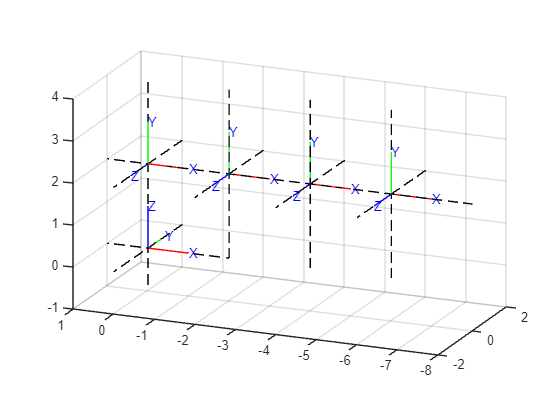

trplot(H0,'rgb','axis', [-2 2 -8 -2 -1 4])

%Realizamos una animación para la siguiente trama
pause;
tranimate(H0, H0_1,'rgb','axis', [-2 2 -8 1 -1 4])

%Realizamos una animación para la siguiente trama
pause;
tranimate(H0_1, H1_2,'rgb','axis', [-2 2 -8 1 -1 4])

%Realizamos una animación para la siguiente trama
pause;           
tranimate(H1_2, H2_3,'rgb','axis', [-2 2 -8 1 -1 4])

%Realizamos una animación para la siguiente trama
pause;           
tranimate(H2_3, H3_4,'rgb','axis', [-2 2 -8 1 -1 4])

Finalmente, se muestra la última matriz de transformación homogénea, que representa la ubicación y orientación final del sistema respecto al marco de referencia base.

disp('Matriz de transformación homogenea global'); disp(H3_4);

Matriz de transformación homogenea global
     0         0        -1         0
    -1         0         0        -6
     0         1         0         2
     0         0         0         1


## Ejercicio 2

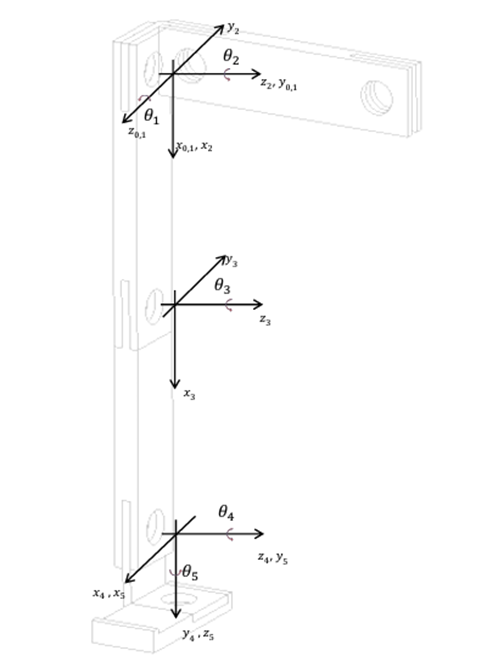

### Modelo Cinemático

#### Declaración de Variables

Se declaran las variables simbólicas, esenciales para realizar cálculos simbólicos y analíticos.

syms th1(t) th2(t) th3(t) th4(t) th5(t) t L1 L2

Se configura el robot con cinco articulaciones rotacionales, representando su tipo con un vector donde 0 es rotacional y 1 prismático

RP=[0 0 0 0 0];

Creamos el vector de coordenadas generalizadas

Q= [th1, th2, th3, th4, th5];
disp('Coordenadas generalizadas'); pretty (Q);

Coordenadas generalizadas
(th1(t), th2(t), th3(t), th4(t), th5(t))



Creamos el vector de velocidades generalizadas.

Qp= diff(Q, t);
disp('Velocidades generalizadas'); pretty (Qp);

Velocidades generalizadas
/  d          d          d          d          d        \
| -- th1(t), -- th2(t), -- th3(t), -- th4(t), -- th5(t) |
\ dt         dt         dt         dt         dt        /



Posteriormente, definimos los grados de libertad (GDL), es decir, el número de parámetros independientes que definen la posición del extremo del robot, en este caso 5 GDL.

GDL= size(RP,2);
GDL_str= num2str(GDL);
P = sym(zeros(3, 1, GDL));

#### Cinemática Directa

La cinemática directa permite encontrar la posición del extremo del robot a partir de sus ángulos articulares. Para ello, se definen los vectores posición (indican la posición relativa de una articulación) y las matrices de rotación (describen la orientación de un sistema de coordenadas respecto a otro) para cada articulación.

**Articulación 1**

No se presenta ningún cambio en los ejes


$$R_z \left(\theta \right)\left\lbrack \begin{array}{ccc}
\cos \theta  & -\textrm{sen}\theta  & 0\\
\textrm{sen}\theta  & \cos \theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$


%Articulación 0 a Articulación 1
%Posición de la articulación 0 a 1
P(:,:,1)= [0;0;0];

%Matriz de rotación de la junta 0 a 1
R(:,:,1)= [cos(th1)  -sin(th1)   0 ;
           sin(th1)   cos(th1)   0 ;
           0          0          1];

**Articulación 2**


$$R_z \left(\theta \right)\left\lbrack \begin{array}{ccc}
\cos \theta  & -\textrm{sen}\theta  & 0\\
\textrm{sen}\theta  & \cos \theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \times R_x \left(-90\right)\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 0 & 1\\
0 & -1 & 0
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
\cos \left(\theta \right) & 0 & -\textrm{sen}\left(\theta \right)\\
\textrm{sen}\left(\theta \right) & 0 & \cos \left(\theta \right)\\
0 & -1 & 0
\end{array}\right\rbrack$$


%Articulación 1 a Articulación 2
%Posición de la articulación 1 a 2
P(:,:,2)= [0;0;0];

%Matriz de rotación de la junta 1 a 2
R(:,:,2)= [cos(th2)   0   -sin(th2);
           sin(th2)   0    cos(th2);
           0         -1          1];

**Articulación 3**

No se presenta ningún cambio en los ejes


$$R_z \left(\theta \right)\left\lbrack \begin{array}{ccc}
\cos \theta  & -\textrm{sen}\theta  & 0\\
\textrm{sen}\theta  & \cos \theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$


%Articulación 2 a Articulación 3
%Posición de la articulación 2 a 3
P(:,:,3)= [L1*cos(th3); L1*sin(th3);0];

%Matriz de rotación de la junta 2 a 3
R(:,:,3)= [cos(th3)  -sin(th3)   0 ;
           sin(th3)   cos(th3)   0 ;
           0          0          1];

**Articulación 4**


$$R_z \left(\theta \right)\left\lbrack \begin{array}{ccc}
\cos \theta  & -\textrm{sen}\theta  & 0\\
\textrm{sen}\theta  & \cos \theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \times R_z \left(90\right)\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
-1 & 0 & 0\\
0 & 0 & 1
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
\textrm{sen}\theta  & \cos \theta  & 0\\
-\cos \theta  & \textrm{sen}\theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$


%Articulación 3 a Articulación 4
%Posición de la articulación 3 a 4
P(:,:,4)= [L2*cos(th4); L2*sin(th4);0];

%Matriz de rotación de la junta 3 a 4
R(:,:,4)= [sin(th4)  cos(th4)   0 ;
          -cos(th4)  sin(th4)   0 ;
           0         0          1];

**Articulación 5**

Se presenta una rotación positiva de 90 en y


$$R_z \left(\theta \right)\left\lbrack \begin{array}{ccc}
\cos \theta  & -\textrm{sen}\theta  & 0\\
\textrm{sen}\theta  & \cos \theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \times R_x \left(90\right)\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 0 & -1\\
0 & 1 & 0
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
\cos \left(\theta \right) & 0 & \textrm{sen}\left(\theta \right)\\
\textrm{sen}\left(\theta \right) & 0 & -\cos \left(\theta \right)\\
0 & 1 & 0
\end{array}\right\rbrack$$


%Articulación 4 a Articulación 5
%Posición de la articulación 4 a 5
P(:,:,5)= [0;0;0];

%Matriz de rotación de la junta 4 a 5
R(:,:,5)= [cos(th5)  0   sin(th5) ;
           sin(th5)  0  -cos(th5) ;
           0         1   0];

Las matrices de transformación homogénea, combinan la rotación y traslación en un solo modelo matemático. Se construyen las matrices locales y globales de transformación para obtener la posición y orientación del extremo del robot en el sistema de referencia inercial.

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL);

%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 

El bucle `for` recorre cada articulación del robot para calcular sus matrices de transformación homogénea locales y globales. Primero, genera la matriz de transformación local, que describe la posición y orientación de la articulación en relación con la anterior. Luego, obtiene la matriz de transformación global, que representa la posición y orientación en el sistema de referencia inercial, acumulando las transformaciones previas. Finalmente, extrae la matriz de rotación y el vector de posición, fundamentales para la cinemática directa y el cálculo del Jacobiano.

for i = 1:GDL
    i_str= num2str(i);

    %Locales
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    disp(strcat('Matriz de Transformación local A', i_str)); pretty(A(:,:,i));
    disp('    ');

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    T(:,:,i)= simplify(T(:,:,i));
    disp(strcat('Matriz de Transformación global T', i_str)); pretty(T(:,:,i));
    disp('    ');

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end

Matriz de Transformación local A1
/ cos(th1(t)), -sin(th1(t)), 0, 0 \
|                                 |
| sin(th1(t)),  cos(th1(t)), 0, 0 |
|                                 |
|      0,            0,      1, 0 |
|                                 |
\      0,            0,      0, 1 /



Matriz de Transformación global T1
/ cos(th1(t)), -sin(th1(t)), 0, 0 \
|                                 |
| sin(th1(t)),  cos(th1(t)), 0, 0 |
|                                 |
|      0,            0,      1, 0 |
|                                 |
\      0,            0,      0, 1 /



Matriz de Transformación local A2
/ cos(th2(t)),  0, -sin(th2(t)), 0 \
|                                  |
| sin(th2(t)),  0,  cos(th2(t)), 0 |
|                                  |
|      0,      -1,       1,      0 |
|                                  |
\      0,       0,       0,      1 /



Matriz de Transformación global T2
/ cos(th1(t) + th2(t)),  0, -sin(th1(t) + th2(t)), 0 \
|                                                    |
| sin(th1(t) + th2(t)),  0,  cos(th1(t) + th2(t)), 0 |
|                                                    |
|           0,          -1,           1,           0 |
|                                                    |
\           0,           0,           0,           1 /



Matriz de Transformación local A3
/ cos(th3(t)), -sin(th3(t)), 0, L1 cos(th3(t)) \
|                                              |
| sin(th3(t)),  cos(th3(t)), 0, L1 sin(th3(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



Matriz de Transformación global T3
/ cos(th3(t)) cos(#1), -sin(th3(t)) cos(#1), -sin(#1), L1 cos(th3(t)) cos(#1) \
|                                                                             |
| cos(th3(t)) sin(#1), -sin(th3(t)) sin(#1),  cos(#1), L1 cos(th3(t)) sin(#1) |
|                                                                             |
|     -sin(th3(t)),        -cos(th3(t)),         1,        -L1 sin(th3(t))    |
|                                                                             |
\          0,                    0,              0,               1           /

where

   #1 == th1(t) + th2(t)




Matriz de Transformación local A4
/  sin(th4(t)), cos(th4(t)), 0, L2 cos(th4(t)) \
|                                              |
| -cos(th4(t)), sin(th4(t)), 0, L2 sin(th4(t)) |
|                                              |
|       0,           0,      1,        0       |
|                                              |
\       0,           0,      0,        1       /



Matriz de Transformación global T4
/ #3 #1, #3 #5, -#2,           #3 #4          \
|                                             |
| #2 #1, #5 #2,  #3,           #2 #4          |
|                                             |
|   #5,   -#1,   1,  - #1 L2 - sin(th3(t)) L1 |
|                                             |
\   0,     0,    0,              1            /

where

   #1 == sin(th3(t) + th4(t))

   #2 == sin(th1(t) + th2(t))

   #3 == cos(th1(t) + th2(t))

   #4 == #5 L2 + cos(th3(t)) L1

   #5 == cos(th3(t) + th4(t))




Matriz de Transformación local A5
/ cos(th5(t)), 0,  sin(th5(t)), 0 \
|                                 |
| sin(th5(t)), 0, -cos(th5(t)), 0 |
|                                 |
|      0,      1,       0,      0 |
|                                 |
\      0,      0,       0,      1 /



Matriz de Transformación global T5
/ #1 #4, -#3, -#2 #4,                    #4 #5                   \
|                                                                |
| #1 #3,  #4, -#2 #3,                    #3 #5                   |
|                                                                |
|   #2,   1,    #1,   - sin(th3(t) + th4(t)) L2 - sin(th3(t)) L1 |
|                                                                |
\   0,    0,     0,                        1                     /

where

   #1 == sin(th3(t) + th4(t) + th5(t))

   #2 == cos(th3(t) + th4(t) + th5(t))

   #3 == sin(th1(t) + th2(t))

   #4 == cos(th1(t) + th2(t))

   #5 == cos(th3(t) + th4(t)) L2 + cos(th3(t)) L1




#### Cálculo del jacobiano lineal de forma diferencial

El Jacobiano es una matriz que relaciona las velocidades articulares con las velocidades lineales y angulares del extremo del robot. El Jacobiano lineal (Jv), relaciona velocidades articulares con velocidad lineal del extremo. Mientras que el Jacobiano angular (Jw), relaciona velocidades articulares con velocidad angular.

El Jacobiano diferencial es obtenido mediante derivadas parciales de la posición.

%Derivadas parciales de x 
Jv11= functionalDerivative(PO(1,1,GDL), th1);
Jv12= functionalDerivative(PO(1,1,GDL), th2);
Jv13= functionalDerivative(PO(1,1,GDL), th3);
Jv14= functionalDerivative(PO(1,1,GDL), th4);
Jv15= functionalDerivative(PO(1,1,GDL), th5);

%Derivadas parciales de y 
Jv21= functionalDerivative(PO(2,1,GDL), th1);
Jv22= functionalDerivative(PO(2,1,GDL), th2);
Jv23= functionalDerivative(PO(2,1,GDL), th3);
Jv24= functionalDerivative(PO(2,1,GDL), th4);
Jv25= functionalDerivative(PO(2,1,GDL), th5);

%Derivadas parciales de z
Jv31= functionalDerivative(PO(3,1,GDL), th1);
Jv32= functionalDerivative(PO(3,1,GDL), th2);
Jv33= functionalDerivative(PO(3,1,GDL), th3);
Jv34= functionalDerivative(PO(3,1,GDL), th4);
Jv35= functionalDerivative(PO(3,1,GDL), th5);

%Creamos la matríz del Jacobiano lineal
jv_d=simplify([Jv11 Jv12 Jv13 Jv14 Jv15;
               Jv21 Jv22 Jv23 Jv24 Jv25;
               Jv31 Jv32 Jv33 Jv34 Jv35]);
disp('Jacobiano lineal obtenido de forma diferencial'); pretty(jv_d);

Jacobiano lineal obtenido de forma diferencial
/ -#2 #1, -#2 #1,                   -#3 #4,                           -L2 #3 #5,        0 \
|                                                                                         |
|  #3 #1,  #3 #1,                   -#2 #4,                           -L2 #2 #5,        0 |
|                                                                                         |
\    0,      0,   - cos(th3(t) + th4(t)) L2 - cos(th3(t)) L1, -L2 cos(th3(t) + th4(t)), 0 /

where

   #1 == cos(th3(t) + th4(t)) L2 + cos(th3(t)) L1

   #2 == sin(th1(t) + th2(t))

   #3 == cos(th1(t) + th2(t))

   #4 == #5 L2 + sin(th3(t)) L1

   #5 == sin(th3(t) + th4(t))




#### Cálculo del jacobiano lineal y angular de forma analítica

El jacobiano analítico es calculado mediante productos vectoriales, considerando el tipo de articulación

%Inicializamos jacobianos analíticos (lineal y angular)
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

Para articulaciones rotacionales, la velocidad lineal se obtiene mediante el producto cruzado entre el eje de rotación y la diferencia de posiciones, mientras que la velocidad angular se toma directamente del eje de rotación. Si no hay una matriz de rotación previa, se usa la identidad y la posición inicial. Para articulaciones prismáticas, la velocidad lineal es el eje de desplazamiento, y la angular es cero, ya que no hay rotación.

for k= 1:GDL
    if RP(k)==0 %Casos: articulación rotacional
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));
            Jw_a(:,k)=[0,0,1];
         end
     
     elseif RP(k)==1 %Casos: articulación prismática
        %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

%Despliegue
Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
disp('Jacobiano lineal obtenido de forma analítica'); pretty (Jv_a);

Jacobiano lineal obtenido de forma analítica
/ #3, #3, - sin(#1) L2 - sin(#2) L1,        -L2 sin(#1),       0 \
|                                                                |
| #4, #4,  cos(#1) L2 + cos(#2) L1,         L2 cos(#1),        0 |
|                                                                |
\  0,  0,   - #6 - cos(th3(t)) L1,   -L2 cos(th3(t) + th4(t)), 0 /

where

   #1 == th1(t) + th2(t) + th3(t) + th4(t)

   #2 == th1(t) + th2(t) + th3(t)

   #3 == -sin(th1(t) + th2(t)) #5

   #4 == cos(th1(t) + th2(t)) #5

   #5 == #6 + cos(th3(t)) L1

   #6 == cos(th3(t) + th4(t)) L2




disp('Jacobiano ángular obtenido de forma analítica'); pretty(Jw_a);

Jacobiano ángular obtenido de forma analítica
/ 0, 0, -sin(th1(t) + th2(t)), -sin(th1(t) + th2(t)), -sin(th1(t) + th2(t)) \
|                                                                           |
| 0, 0,  cos(th1(t) + th2(t)),  cos(th1(t) + th2(t)),  cos(th1(t) + th2(t)) |
|                                                                           |
\ 1, 1,           1,                     1,                     1           /



#### Velocidades Lineales y Angulares

Finalmente, se obtienen las velocidades multiplicando los jacobianos por el vector de velocidades articulares

La velocidad lineal describe el desplazamiento del efector.

V=simplify (Jv_a*Qp');
disp('Velocidad lineal obtenida mediante el Jacobiano lineal'); pretty(V);

Velocidad lineal obtenida mediante el Jacobiano lineal
/ - #3 (sin(#1) L2 + sin(#4) L1) - L2 #2 sin(#1) - #7 sin(#5) #8 - #6 sin(#5) #8 \
|                                                                                |
|  #3 (cos(#1) L2 + cos(#4) L1) + L2 #2 cos(#1) + #7 cos(#5) #8 + #6 cos(#5) #8  |
|                                                                                |
\                               - #3 #8 - L2 #2 #9                               /

where

   #1 == th1(t) + th2(t) + th3(t) + th4(t)

         _________
          d
   #2 == -- th4(t)
         dt

         _________
          d
   #3 == -- th3(t)
         dt

   #4 == th1(t) + th2(t) + th3(t)

   #5 == th1(t) + th2(t)

         _________
          d
   #6 == -- th2(t)
         dt

         _________
          d
   #7 == -- th1(t)
         dt

   #8 == #9 L2 + cos(th3(t)) L1

   #9 == cos(th3(t) + th4(t))




Mientras que la velocidad angular describe la rotación del efector.

W=simplify (Jw_a*Qp');
disp('Velocidad angular obtenida mediante el Jacobiano angular'); pretty(W);

Velocidad angular obtenida mediante el Jacobiano angular
/                  -sin(th1(t) + th2(t)) #1                 \
|                                                           |
|                  cos(th1(t) + th2(t)) #1                  |
|                                                           |
| _________   _________   _________   _________   _________ |
|  d           d           d           d           d        |
| -- th1(t) + -- th2(t) + -- th3(t) + -- th4(t) + -- th5(t) |
\ dt          dt          dt          dt          dt        /

where

         _________   _________   _________
          d           d           d
   #1 == -- th3(t) + -- th4(t) + -- th5(t)
         dt          dt          dt




### Animación

#### Calculo de las matrices de transformación homogénea

Se calculan varias matrices de transformación homogénea,  estas matrices describen rotaciones y traslaciones en el espacio tridimensional, que serán encadenadas para obtener una transformación global desde el marco de referencia base hasta un marco final.

H0=SE3(roty(pi/2), [0 0 0]);
H1=SE3(roty(0), [0 0 0]);
H2=SE3(rotx(-pi/2), [0 0 0]);
H3=SE3(rotz(0), [2 0 0]);
H4=SE3(rotz(-pi/2), [2 0 0]);
H5=SE3(rotx(pi/2), [0 0 0]);

Estas matrices se multiplican secuencialmente para obtener las transformaciones compuestas, siendo la última la transformación global desde el sistema de referencia del objeto final hasta el sistema base.

H0_1 = H0*H1;
H1_2 = H0_1*H2;
H2_3 = H1_2*H3;
H3_4 = H2_3*H4;
H4_5 = H3_4*H5;

#### Coordenadas de la estructura de translación y rotación

Se definen los vectores $x$, $y$ y $z$ que contienen las coordenadas de los vértices de una estructura tridimensional que se desea visualizar. Se utiliza la función `plot3` para graficar esta estructura con líneas tridimensionales, y se configura la visualización del espacio con límites y una cuadrícula para una mejor interpretación gráfica.

x=[ 0 0];
y=[ 0 0];
z=[2 -8];
plot3(x, y, z, 'k--', 'LineWidth', 0.5); axis([-2 2 -2 2 -6 2]);
view(-231, 12);
axis equal;
grid on;
hold on;

x=[ 0  0];
y=[-2  2];
z=[ 0  0];
plot3(x, y, z, 'k--', 'LineWidth', 0.5); axis([-2 2 -2 2 -6 2]);

x=[-2  2];
y=[ 0  0];
z=[ 0  0];
plot3(x, y, z, 'k--', 'LineWidth', 0.5); axis([-2 2 -2 2 -6 2]);

x=[ 0  0];
y=[-2  2];
z=[-2  -2];
plot3(x, y, z, 'k--', 'LineWidth', 0.5); axis([-2 2 -2 2 -6 2]);

x=[-2  2];
y=[ 0  0];
z=[-2 -2];
plot3(x, y, z, 'k--', 'LineWidth', 0.5); axis([-2 2 -2 2 -6 2]);

x=[ 0  0];
y=[-2  2];
z=[-4 -4];
plot3(x, y, z, 'k--', 'LineWidth', 0.5); axis([-2 2 -2 2 -6 2]);

x=[-2  2];
y=[ 0  0];
z=[-4 -4];
plot3(x, y, z, 'k--', 'LineWidth', 0.5); axis([-2 2 -2 2 -6 2]);

#### Grafica de la trama absoluta o global

Se grafica la trama del marco de referencia global utilizando la función `trplot`, que muestra los ejes coordenados de un sistema de referencia homogéneo. Después de cada transformación, se realiza una animación con la función `tranimate` para visualizar la transición de un marco a otro. Cada animación está separada por una pausa para permitir al usuario observar cada paso de la transformación.

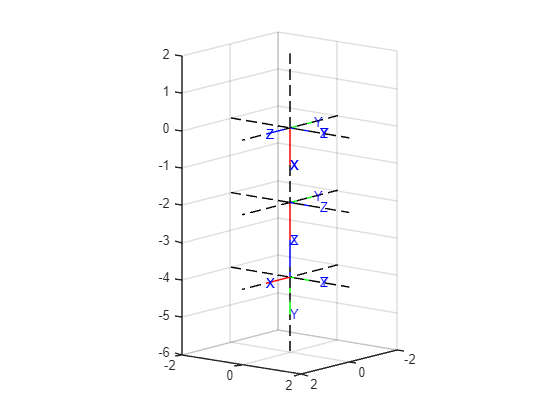

trplot(H0,'rgb','axis', [-2 2 -2 2 -6 4])
% 
% %Realizamos una animación para la siguiente trama
 pause;
  tranimate(H0, H0_1,'rgb','axis', [-2 2 -2 2 -6 2])
% %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H0_1, H1_2,'rgb','axis', [-2 2 -2 2 -6 2])
% % %Realizamos una animación para la siguiente trama
 pause;           
  tranimate(H1_2, H2_3,'rgb','axis', [-2 2 -2 2 -6 2])

  % % %Realizamos una animación para la siguiente trama
 pause;           
  tranimate(H2_3, H3_4,'rgb','axis', [-2 2 -2 2 -6 2])

% % %Realizamos una animación para la siguiente trama
 pause;           
  tranimate(H3_4, H4_5,'rgb','axis', [-2 2 -2 2 -6 2])

Finalmente, se muestra la última matriz de transformación homogénea, que representa la ubicación y orientación final del sistema respecto al marco de referencia base.

 disp('Matriz de transformación homogenea global'); disp(H4_5)

Matriz de transformación homogenea global
    1         0         0         0
    0         1         0         0
    0         0         1        -4
    0         0         0         1


## Ejercicio 3

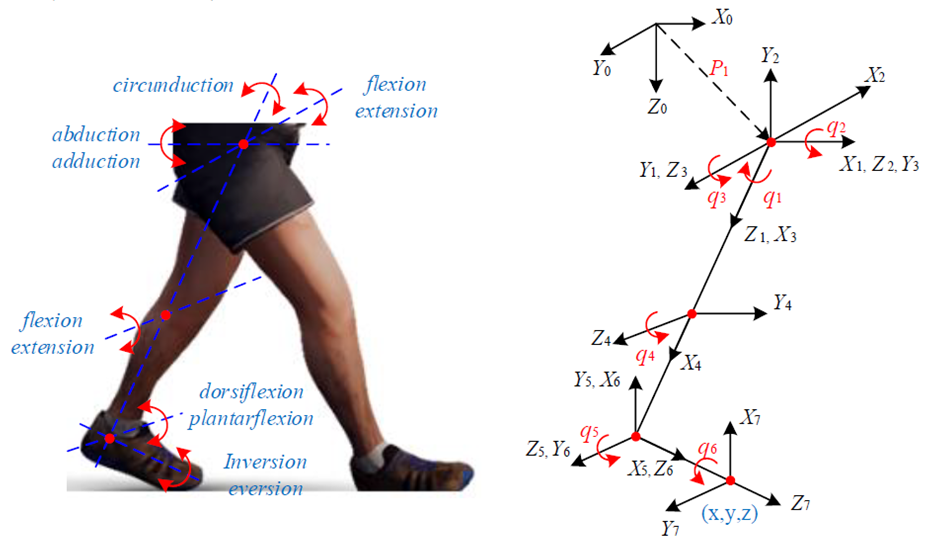

### Modelo Cinemático

#### Declaración de Variables

Se declaran las variables simbólicas, esenciales para realizar cálculos simbólicos y analíticos.

syms th0(t) th1(t) th2(t) th3(t) th4(t) th5(t) th6(t) t L1 L2 L3

Se configura el robot con siete articulaciones rotacionales, representando su tipo con un vector donde 0 es rotacional y 1 prismático

RP=[0 0 0 0 0 0 0];

Creamos el vector de coordenadas generalizadas

Q= [th0, th1, th2, th3, th4, th5, th6];
disp('Coordenadas generalizadas'); pretty (Q);

Coordenadas generalizadas
(th0(t), th1(t), th2(t), th3(t), th4(t), th5(t), th6(t))



Creamos el vector de velocidades generalizadas.

Qp= diff(Q, t);
disp('Velocidades generalizadas'); pretty (Qp);

Velocidades generalizadas
/  d          d          d          d          d          d          d        \
| -- th0(t), -- th1(t), -- th2(t), -- th3(t), -- th4(t), -- th5(t), -- th6(t) |
\ dt         dt         dt         dt         dt         dt         dt        /



Posteriormente, definimos los grados de libertad (GDL), es decir, el número de parámetros independientes que definen la posición del extremo del robot, en este caso 7 GDL.

GDL= size(RP,2);
GDL_str= num2str(GDL);
P = sym(zeros(3, 1, GDL));

#### Cinemática Directa

La cinemática directa permite encontrar la posición del extremo del robot a partir de sus ángulos articulares. Para ello, se definen los vectores posición (indican la posición relativa de una articulación) y las matrices de rotación (describen la orientación de un sistema de coordenadas respecto a otro) para cada articulación.

**Articulación 1**

No se presenta ningún cambio en los ejes


$$R_z \left(\theta \right)\left\lbrack \begin{array}{ccc}
\cos \theta  & -\textrm{sen}\theta  & 0\\
\textrm{sen}\theta  & \cos \theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$


%Articulación 0 a Articulación 1
%Posición de la articulación 0 a 1
P(:,:,1)= [0;0;0];

%Matriz de rotación de la junta 0 a 1
R(:,:,1)= [cos(th0)  -sin(th0)   0 ;
           sin(th0)   cos(th0)   0 ;
           0          0          1];

**Articulación 2**


$$R_z \left(\theta \right)\left\lbrack \begin{array}{ccc}
\cos \theta  & -\textrm{sen}\theta  & 0\\
\textrm{sen}\theta  & \cos \theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \times R_x \left(-90\right)\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 0 & 1\\
0 & -1 & 0
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
\cos \left(\theta \right) & 0 & -\textrm{sen}\left(\theta \right)\\
\textrm{sen}\left(\theta \right) & 0 & \cos \left(\theta \right)\\
0 & -1 & 0
\end{array}\right\rbrack$$



$$\left\lbrack \begin{array}{ccc}
\cos \left(\theta \right) & 0 & -\textrm{sen}\left(\theta \right)\\
\textrm{sen}\left(\theta \right) & 0 & \cos \left(\theta \right)\\
0 & -1 & 0
\end{array}\right\rbrack \times R_y \left(90\right)\left\lbrack \begin{array}{ccc}
0 & 0 & 1\\
0 & 1 & 0\\
-1 & 0 & 0
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
\textrm{sen}\theta  & 0 & \cos \theta \\
-\cos \theta  & 0 & \textrm{sen}\theta \\
0 & -1 & 0
\end{array}\right\rbrack$$


%Articulación 1 a Articulación 2
%Posición de la articulación 1 a 2
P(:,:,2)= [0;0;0];

%Matriz de rotación de la junta 1 a 2
R(:,:,2)= [sin(th1)   0   cos(th1);
          -cos(th1)   0   sin(th1);
           0         -1          0];

**Articulación 3**


$$R_z \left(\theta \right)\left\lbrack \begin{array}{ccc}
\cos \theta  & -\textrm{sen}\theta  & 0\\
\textrm{sen}\theta  & \cos \theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \times R_z \left(-90\right)\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
-1 & 0 & 0\\
0 & 0 & 1
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
\textrm{sen}\theta  & \cos \theta  & 0\\
-\cos \theta  & \textrm{sen}\theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$



$$\left\lbrack \begin{array}{ccc}
\textrm{sen}\theta  & \cos \theta  & 0\\
-\cos \theta  & \textrm{sen}\theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \times R_x \left(90\right)\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 0 & -1\\
0 & 1 & 0
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
\textrm{sen}\theta  & 0 & -\cos \theta \\
-\cos \theta  & 0 & -\textrm{sen}\theta \\
0 & 1 & 0
\end{array}\right\rbrack$$


%Articulación 2 a Articulación 3
%Posición de la articulación 2 a 3
P(:,:,3)= [0;0;0];

%Matriz de rotación de la junta 2 a 3
R(:,:,3)= [sin(th2)   0  -cos(th2);
          -cos(th2)   0  -sin(th2);
           0          1          0];

**Articulación 4**

No se presenta ningún cambio en los ejes


$$R_z \left(\theta \right)\left\lbrack \begin{array}{ccc}
\cos \theta  & -\textrm{sen}\theta  & 0\\
\textrm{sen}\theta  & \cos \theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$


%Articulación 3 a Articulación 4
%Posición de la articulación 3 a 4
P(:,:,4)= [L1*cos(th3); L1*sin(th3);0];

%Matriz de rotación de la junta 3 a 4
R(:,:,4)= [cos(th3)  -sin(th3)   0 ;
           sin(th3)   cos(th3)   0 ;
           0          0          1];

**Articulación 5**


$$R_z \left(\theta \right)\left\lbrack \begin{array}{ccc}
\cos \theta  & -\textrm{sen}\theta  & 0\\
\textrm{sen}\theta  & \cos \theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \times R_z \left(90\right)\left\lbrack \begin{array}{ccc}
0 & -1 & 0\\
1 & 0 & 0\\
0 & 0 & 1
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
-\textrm{sen}\left(\theta \right) & -\cos \theta  & 0\\
\cos \theta  & -\textrm{sen}\theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$


%Articulación 4 a Articulación 5
%Posición de la articulación 4 a 5
P(:,:,5)= [L2*cos(th4); L2*sin(th4);0];

%Matriz de rotación de la junta 4 a 5
R(:,:,5)= [-sin(th4)  -cos(th4)   0;
            cos(th4)  -sin(th4)   0;
            0          0          1];

**Articulación 6**


$$R_z \left(\theta \right)\left\lbrack \begin{array}{ccc}
\cos \theta  & -\textrm{sen}\theta  & 0\\
\textrm{sen}\theta  & \cos \theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \times R_y \left(90\right)\left\lbrack \begin{array}{ccc}
0 & 0 & 1\\
0 & 1 & 0\\
-1 & 0 & 0
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
0 & -\textrm{sen}\left(\theta \right) & \cos \left(\theta \right)\\
0 & \cos \left(\theta \right) & \textrm{sen}\left(\theta \right)\\
-1 & 0 & 0
\end{array}\right\rbrack$$



$$\left\lbrack \begin{array}{ccc}
0 & -\textrm{sen}\left(\theta \right) & \cos \left(\theta \right)\\
0 & \cos \left(\theta \right) & \textrm{sen}\left(\theta \right)\\
-1 & 0 & 0
\end{array}\right\rbrack \times R_z \left(90\right)\left\lbrack \begin{array}{ccc}
0 & -1 & 0\\
1 & 0 & 0\\
0 & 0 & 1
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
-\textrm{sen}\left(\theta \right) & 0 & \cos \left(\theta \right)\\
\cos \left(\theta \right) & 0 & \textrm{sen}\left(\theta \right)\\
0 & 1 & 0
\end{array}\right\rbrack$$


%Articulación 5 a Articulación 6
%Posición de la articulación 5 a 6
P(:,:,6)= [0;0;0];

%Matriz de rotación de la junta 5 a 6
R(:,:,6)= [-sin(th5)  0   cos(th5);
            cos(th5)  0   sin(th5);
            0         1          0];

**Articulación 7**

No se presenta ningún cambio en los ejes


$$R_z \left(\theta \right)\left\lbrack \begin{array}{ccc}
\cos \theta  & -\textrm{sen}\theta  & 0\\
\textrm{sen}\theta  & \cos \theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$


%Articulación 6 a Articulación 7
%Posición de la articulación 6 a 7
P(:,:,7)= [0;0;L3];

%Matriz de rotación de la junta 6 a 7
R(:,:,7)= [cos(th6)  -sin(th6)   0 ;
           sin(th6)   cos(th6)   0 ;
           0          0          1];

Las matrices de transformación homogénea, combinan la rotación y traslación en un solo modelo matemático. Se construyen las matrices locales y globales de transformación para obtener la posición y orientación del extremo del robot en el sistema de referencia inercial.

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL);

%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 

El bucle `for` recorre cada articulación del robot para calcular sus matrices de transformación homogénea locales y globales. Primero, genera la matriz de transformación local, que describe la posición y orientación de la articulación en relación con la anterior. Luego, obtiene la matriz de transformación global, que representa la posición y orientación en el sistema de referencia inercial, acumulando las transformaciones previas. Finalmente, extrae la matriz de rotación y el vector de posición, fundamentales para la cinemática directa y el cálculo del Jacobiano.

for i = 1:GDL
    i_str= num2str(i);

    %Locales
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    disp(strcat('Matriz de Transformación local A', i_str)); pretty(A(:,:,i));
    disp('    ');

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    T(:,:,i)= simplify(T(:,:,i));
    disp(strcat('Matriz de Transformación global T', i_str)); pretty(T(:,:,i));
    disp('    ');

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end

Matriz de Transformación local A1
/ cos(th0(t)), -sin(th0(t)), 0, 0 \
|                                 |
| sin(th0(t)),  cos(th0(t)), 0, 0 |
|                                 |
|      0,            0,      1, 0 |
|                                 |
\      0,            0,      0, 1 /



Matriz de Transformación global T1
/ cos(th0(t)), -sin(th0(t)), 0, 0 \
|                                 |
| sin(th0(t)),  cos(th0(t)), 0, 0 |
|                                 |
|      0,            0,      1, 0 |
|                                 |
\      0,            0,      0, 1 /



Matriz de Transformación local A2
/  sin(th1(t)),  0, cos(th1(t)), 0 \
|                                  |
| -cos(th1(t)),  0, sin(th1(t)), 0 |
|                                  |
|       0,      -1,      0,      0 |
|                                  |
\       0,       0,      0,      1 /



Matriz de Transformación global T2
/  sin(th0(t) + th1(t)),  0, cos(th0(t) + th1(t)), 0 \
|                                                    |
| -cos(th0(t) + th1(t)),  0, sin(th0(t) + th1(t)), 0 |
|                                                    |
|           0,           -1,           0,          0 |
|                                                    |
\           0,            0,           0,          1 /



Matriz de Transformación local A3
/  sin(th2(t)), 0, -cos(th2(t)), 0 \
|                                  |
| -cos(th2(t)), 0, -sin(th2(t)), 0 |
|                                  |
|       0,      1,       0,      0 |
|                                  |
\       0,      0,       0,      1 /



Matriz de Transformación global T3
/  sin(th2(t)) #1, #2, -cos(th2(t)) #1, 0 \
|                                         |
| -sin(th2(t)) #2, #1,  cos(th2(t)) #2, 0 |
|                                         |
|   cos(th2(t)),    0,   sin(th2(t)),   0 |
|                                         |
\        0,         0,        0,        1 /

where

   #1 == sin(th0(t) + th1(t))

   #2 == cos(th0(t) + th1(t))




Matriz de Transformación local A4
/ cos(th3(t)), -sin(th3(t)), 0, L1 cos(th3(t)) \
|                                              |
| sin(th3(t)),  cos(th3(t)), 0, L1 sin(th3(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



Matriz de Transformación global T4
/ sin(th3(t)) cos(#1) + cos(th3(t)) sin(th2(t)) sin(#1), cos(th3(t)) cos(#1) - sin(th2(t)) sin(th3(t)) sin(#1), -cos(th2(t)) sin(#1), L1 sin(th3(t)) cos(#1) + L1 cos(th3(t)) sin(th2(t)) sin(#1) \
|                                                                                                                                                                                                 |
| sin(th3(t)) sin(#1) - cos(th3(t)) sin(th2(t)) cos(#1), cos(th3(t)) sin(#1) + sin(th2(t)) sin(th3(t)) cos(#1),  cos(th2(t)) cos(#1), L1 sin(th3(t)) sin(#1) - L1 cos(th3(t)) sin(th2(t)) cos(#1) |
|                                                                                                                                                                                                 |
|                cos(th2(t)) cos(th3(t)),                               -cos(th2(t)) sin(th3(t)),                    sin(th2(t)),                      L1 cos(th2(t)) cos(th3(t))    

Matriz de Transformación local A5
/ -sin(th4(t)), -cos(th4(t)), 0, L2 cos(th4(t)) \
|                                               |
|  cos(th4(t)), -sin(th4(t)), 0, L2 sin(th4(t)) |
|                                               |
|       0,            0,      1,        0       |
|                                               |
\       0,            0,      0,        1       /



Matriz de Transformación global T5
/ cos(th4(t)) #3 - sin(th4(t)) #4, - cos(th4(t)) #4 - sin(th4(t)) #3, -cos(th2(t)) sin(#6), L2 cos(th4(t)) #4 + L2 sin(th4(t)) #3 + L1 sin(th3(t)) cos(#6) + L1 cos(th3(t)) sin(th2(t)) sin(#6) \
|                                                                                                                                                                                               |
| cos(th4(t)) #5 - sin(th4(t)) #2, - cos(th4(t)) #2 - sin(th4(t)) #5,  cos(th2(t)) cos(#6), L2 cos(th4(t)) #2 + L2 sin(th4(t)) #5 + L1 sin(th3(t)) sin(#6) - L1 cos(th3(t)) sin(th2(t)) cos(#6) |
|                                                                                                                                                                                               |
|       -cos(th2(t)) sin(#1),             -cos(th2(t)) cos(#1),            sin(th2(t)),                                  cos(th2(t)) (cos(#1) L2 + cos(th3(t)) L1)                           

Matriz de Transformación local A6
/ -sin(th5(t)), 0, cos(th5(t)), 0 \
|                                 |
|  cos(th5(t)), 0, sin(th5(t)), 0 |
|                                 |
|       0,      1,      0,      0 |
|                                 |
\       0,      0,      0,      1 /



Matriz de Transformación global T6
/ - cos(th5(t)) #5 - sin(th5(t)) #2, -cos(th2(t)) sin(#10), cos(th5(t)) #2 - sin(th5(t)) #5, L2 cos(th4(t)) #9 + L2 sin(th4(t)) #8 + L1 sin(th3(t)) cos(#10) + L1 cos(th3(t)) sin(th2(t)) sin(#10) \
|                                                                                                                                                                                                  |
| - cos(th5(t)) #4 - sin(th5(t)) #3,  cos(th2(t)) cos(#10), cos(th5(t)) #3 - sin(th5(t)) #4, L2 cos(th4(t)) #6 + L2 sin(th4(t)) #7 + L1 sin(th3(t)) sin(#10) - L1 cos(th3(t)) sin(th2(t)) cos(#10) |
|                                                                                                                                                                                                  |
|        -cos(th2(t)) cos(#1),            sin(th2(t)),            -cos(th2(t)) sin(#1),                              cos(th2(t)) (cos(th3(t) + th4(t)) L2 + cos(th3(t)) L1)      

Matriz de Transformación local A7
/ cos(th6(t)), -sin(th6(t)), 0,  0 \
|                                  |
| sin(th6(t)),  cos(th6(t)), 0,  0 |
|                                  |
|      0,            0,      1, L3 |
|                                  |
\      0,            0,      0,  1 /



Matriz de Transformación global T7
/    - cos(th6(t)) #5 - cos(th2(t)) sin(th6(t)) sin(#14),        sin(th6(t)) #5 - cos(th2(t)) cos(th6(t)) sin(#14),              #2,          L3 #2 + L2 cos(th4(t)) #13 + L2 sin(th4(t)) #12 + L1 sin(th3(t)) cos(#14) + L1 cos(th3(t)) sin(th2(t)) sin(#14) \
|                                                                                                                                                                                                                                                             |
|     cos(th2(t)) sin(th6(t)) cos(#14) - cos(th6(t)) #4,         sin(th6(t)) #4 + cos(th2(t)) cos(th6(t)) cos(#14),              #3,          L3 #3 + L2 cos(th4(t)) #10 + L2 sin(th4(t)) #11 + L1 sin(th3(t)) sin(#14) - L1 cos(th3(t)) sin(th2(t)) cos(#14) |
|                                                                                                                                                                                                    

#### Cálculo del jacobiano lineal de forma diferencial

El Jacobiano es una matriz que relaciona las velocidades articulares con las velocidades lineales y angulares del extremo del robot. El Jacobiano lineal (Jv), relaciona velocidades articulares con velocidad lineal del extremo. Mientras que el Jacobiano angular (Jw), relaciona velocidades articulares con velocidad angular.

El Jacobiano diferencial es obtenido mediante derivadas parciales de la posición.

%Derivadas parciales de x 
Jv11= functionalDerivative(PO(1,1,GDL), th0);
Jv12= functionalDerivative(PO(1,1,GDL), th1);
Jv13= functionalDerivative(PO(1,1,GDL), th2);
Jv14= functionalDerivative(PO(1,1,GDL), th3);
Jv15= functionalDerivative(PO(1,1,GDL), th4);
Jv16= functionalDerivative(PO(1,1,GDL), th5);
Jv17= functionalDerivative(PO(1,1,GDL), th6);

%Derivadas parciales de y 
Jv21= functionalDerivative(PO(2,1,GDL), th0);
Jv22= functionalDerivative(PO(2,1,GDL), th1);
Jv23= functionalDerivative(PO(2,1,GDL), th2);
Jv24= functionalDerivative(PO(2,1,GDL), th3);
Jv25= functionalDerivative(PO(2,1,GDL), th4);
Jv26= functionalDerivative(PO(2,1,GDL), th5);
Jv27= functionalDerivative(PO(2,1,GDL), th6);

%Derivadas parciales de z
Jv31= functionalDerivative(PO(3,1,GDL), th0);
Jv32= functionalDerivative(PO(3,1,GDL), th1);
Jv33= functionalDerivative(PO(3,1,GDL), th2);
Jv34= functionalDerivative(PO(3,1,GDL), th3);
Jv35= functionalDerivative(PO(3,1,GDL), th4);
Jv36= functionalDerivative(PO(3,1,GDL), th5);
Jv37= functionalDerivative(PO(3,1,GDL), th6);

%Creamos la matríz del Jacobiano lineal
jv_d=simplify([Jv11 Jv12 Jv13 Jv14 Jv15 Jv16 Jv17;
               Jv21 Jv22 Jv23 Jv24 Jv25 Jv26 Jv27;
               Jv31 Jv32 Jv33 Jv34 Jv35 Jv36 Jv37]);
disp('Jacobiano lineal obtenido de forma diferencial'); pretty(jv_d);

Jacobiano lineal obtenido de forma diferencial
/ #1, #1,  cos(th2(t)) sin(#30) #3, L1 cos(th3(t)) cos(#30) - L1 sin(th2(t)) sin(th3(t)) sin(#30) + #26 - #24 - #14 - #13 - #12 - #23 - #22 + #18 - #11 + #9 + #8 + #7, #26 - #24 - #14 - #13 - #12 - #23 - #22 + #18 - #11 + #9 + #8 + #7,  L3 (sin(th3(t)) sin(th4(t)) sin(th5(t)) cos(#30) - cos(th3(t)) cos(th4(t)) sin(th5(t)) cos(#30) - cos(th3(t)) cos(th5(t)) sin(th4(t)) cos(#30) - cos(th4(t)) cos(th5(t)) sin(th3(t)) cos(#30) - cos(th3(t)) cos(th4(t)) cos(th5(t)) sin(th2(t)) sin(#30) + cos(th3(t)) sin(th2(t)) sin(th4(t)) sin(th5(t)) sin(#30) + cos(th4(t)) sin(th2(t)) sin(th3(t)) sin(th5(t)) sin(#30) + cos(th5(t)) sin(th2(t)) sin(th3(t)) sin(th4(t)) sin(#30)), 0 \
|                                                                                                                                                                                                                                                                                           

#### Cálculo del jacobiano lineal y angular de forma analítica

El jacobiano analítico es calculado mediante productos vectoriales, considerando el tipo de articulación

%Inicializamos jacobianos analíticos (lineal y angular)
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

Para articulaciones rotacionales, la velocidad lineal se obtiene mediante el producto cruzado entre el eje de rotación y la diferencia de posiciones, mientras que la velocidad angular se toma directamente del eje de rotación. Si no hay una matriz de rotación previa, se usa la identidad y la posición inicial. Para articulaciones prismáticas, la velocidad lineal es el eje de desplazamiento, y la angular es cero, ya que no hay rotación.

for k= 1:GDL
    if RP(k)==0 %Casos: articulación rotacional
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));
            Jw_a(:,k)=[0,0,1];
         end
     
     elseif RP(k)==1 %Casos: articulación prismática
        %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

%Despliegue
Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
disp('Jacobiano lineal obtenido de forma analítica'); pretty (Jv_a);

Jacobiano lineal obtenido de forma analítica
/ #2, #2,                         sin(#37) #4,                         L1 cos(th3(t)) cos(#37) - L1 sin(th2(t)) sin(th3(t)) sin(#37) + #27 - #25 - #15 - #14 - #13 - #24 - #23 + #19 - #12 + #10 + #9 + #8, #27 - #25 - #15 - #14 - #13 - #24 - #23 + #19 - #12 + #10 + #9 + #8,                      - L3 sin(th2(t)) #29 - L3 #1 sin(#31) cos(#37),                     0 \
|                                                                                                                                                                                                                                                                                                                                                                           |
| #3, #3,                         -cos(#37) #4,                         L1 cos(th3(t)) sin(#37) - #26 + #28 + L1 sin(th2(t)) sin(th3(t)) cos(#37) + #22 + #21 - #18 - #17 - #16 + #20 + #11 - #7 - #6 - #5,  #28 - #26 + #22 + 

disp('Jacobiano ángular obtenido de forma analítica'); pretty(Jw_a);

Jacobiano ángular obtenido de forma analítica
/ 0, 0, cos(#7),      #5,          #5,          #5,     cos(th5(t)) (cos(th4(t)) #2 - sin(th4(t)) #3) - sin(th5(t)) (cos(th4(t)) #3 + sin(th4(t)) #2) \
|                                                                                                                                                     |
| 0, 0, sin(#7),      #6,          #6,          #6,     cos(th5(t)) (cos(th4(t)) #4 - sin(th4(t)) #1) - sin(th5(t)) (cos(th4(t)) #1 + sin(th4(t)) #4) |
|                                                                                                                                                     |
\ 1, 1,    0,    sin(th2(t)), sin(th2(t)), sin(th2(t)),                           -cos(th2(t)) sin(th3(t) + th4(t) + th5(t))                          /

where

   #1 == sin(th3(t)) sin(#7) - cos(th3(t)) sin(th2(t)) cos(#7)

   #2 == cos(th3(t)) cos(#7) - sin(th2(t)) sin(th3(t)) sin(#7)

   #3 == sin(th3(t)) cos(#7) + cos(th3(t)) sin(th2(t)) sin

#### Velocidades Lineales y Angulares

Finalmente, se obtienen las velocidades multiplicando los jacobianos por el vector de velocidades articulares

La velocidad lineal describe el desplazamiento del efector.

V=simplify (Jv_a*Qp');
disp('Velocidad lineal obtenida mediante el Jacobiano lineal'); pretty(V);

Velocidad lineal obtenida mediante el Jacobiano lineal
/ #4 sin(#43) #10 - #3 (L1 sin(th2(t)) sin(th3(t)) sin(#43) - L1 cos(th3(t)) cos(#43) - #33 + #31 + #21 + #20 + #19 + #30 + #29 - #25 + #18 - #16 - #15 - #14) - #7 #8 - #6 #8 - #2 (#31 - #33 + #21 + #20 + #19 + #30 + #29 - #25 + #18 - #16 - #15 - #14) - #1 (L3 sin(th2(t)) #35 + L3 #5 sin(#37) cos(#43)) \
|                                                                                                                                                                                                                                                                                                               |
| #1 (L3 sin(th2(t)) #36 - L3 #5 sin(#37) sin(#43)) + #3 (L1 cos(th3(t)) sin(#43) - #32 + #34 + L1 sin(th2(t)) sin(th3(t)) cos(#43) + #28 + #27 - #24 - #23 - #22 + #26 + #17 - #13 - #12 - #11) + #7 #9 + #6 #9 - #2 (#32 - #34 - #28 - #27 + #24 + #23 + #22 - #26 - #17 + #13 + #12 + #11) - #4 cos(#43) #10 |
|                          

Mientras que la velocidad angular describe la rotación del efector.

W=simplify (Jw_a*Qp');
disp('Velocidad angular obtenida mediante el Jacobiano angular'); pretty(W);

Velocidad angular obtenida mediante el Jacobiano angular
/ #5 cos(#10) + #1 (cos(th5(t)) (cos(th4(t)) #7 - sin(th4(t)) #8) - sin(th5(t)) (cos(th4(t)) #8 + sin(th4(t)) #7)) - #4 cos(th2(t)) sin(#10) - #3 cos(th2(t)) sin(#10) - #2 cos(th2(t)) sin(#10) \
|                                                                                                                                                                                                |
| #5 sin(#10) + #1 (cos(th5(t)) (cos(th4(t)) #9 - sin(th4(t)) #6) - sin(th5(t)) (cos(th4(t)) #6 + sin(th4(t)) #9)) + #4 cos(th2(t)) cos(#10) + #3 cos(th2(t)) cos(#10) + #2 cos(th2(t)) cos(#10) |
|                                                                                                                                                                                                |
|                                     _________   _________                                                                                                        

### Animación

#### Calculo de las matrices de transformación homogénea

Se calculan varias matrices de transformación homogénea,  estas matrices describen rotaciones y traslaciones en el espacio tridimensional, que serán encadenadas para obtener una transformación global desde el marco de referencia base hasta un marco final.

H0=SE3(roty(pi), [0 0 0]);
H1=SE3(roty(0), [0 0 0]);
H21=SE3(rotx(-pi/2), [0 0 0]);
H2=SE3(roty(pi/2), [0 0 0]);
H31=SE3(rotz(-pi/2), [0 0 0]);
H3=SE3(rotx(90), [0 0 0]);
H4=SE3(rotz(0), [3 0 0]);
H5=SE3(rotz(pi/2), [3 0 0]);
H61=SE3(roty(pi/2), [0 0 0]);
H6=SE3(rotz(pi/2), [0 0 0]);
H7=SE3(rotz(0), [0 0 3]);

Estas matrices se multiplican secuencialmente para obtener las transformaciones compuestas, siendo la última la transformación global desde el sistema de referencia del objeto final hasta el sistema base.

H0_1 = H0*H1;
H1_21 = H0_1*H21;
H21_2 = H1_21*H2;
H2_31 = H21_2*H31;
H31_3 = H2_31*H3;
H3_4 = H31_3*H4;
H4_5 = H3_4*H5;
H5_61 = H4_5*H61;
H61_6 = H5_61*H6;
H6_7 = H61_6*H7;

#### Coordenadas de la estructura de translación y rotación

Se definen los vectores $x$, $y$ y $z$ que contienen las coordenadas de los vértices de una estructura tridimensional que se desea visualizar. Se utiliza la función `plot3` para graficar esta estructura con líneas tridimensionales, y se configura la visualización del espacio con límites y una cuadrícula para una mejor interpretación gráfica.

x=[0  0  0];
y=[0  0  0];
z=[0 -3 -6];
plot3(x, y, z, 'k--', 'LineWidth', 0.5); axis([-6 2 -2 4 -10 2]);
view(-150, 13);
axis equal;
grid on;
hold on;

x=[ 0 -2.68];
y=[ 0  1.35];
z=[-6 -6];
plot3(x, y, z, 'k--', 'LineWidth', 0.5); axis([-6 2 -2 4 -10 2]);

#### Grafica de la trama absoluta o global

Se grafica la trama del marco de referencia global utilizando la función `trplot`, que muestra los ejes coordenados de un sistema de referencia homogéneo. Después de cada transformación, se realiza una animación con la función `tranimate` para visualizar la transición de un marco a otro. Cada animación está separada por una pausa para permitir al usuario observar cada paso de la transformación.

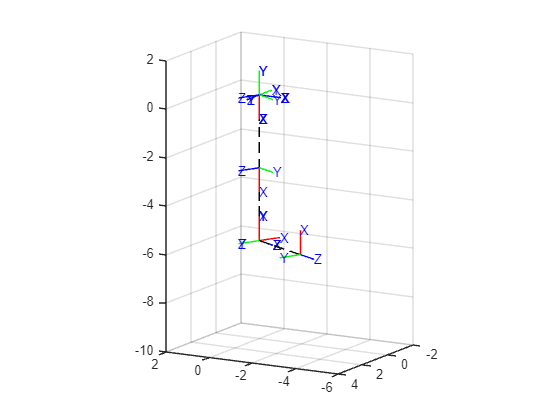

trplot(H0,'rgb','axis', [-6 2 -2 4 -10 2])
% 
% %Realizamos una animación para la siguiente trama
 pause;
  tranimate(H0, H0_1,'rgb','axis', [-6 2 -2 4 -10 2])
% %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H0_1, H1_21,'rgb','axis', [-6 2 -2 4 -10 2])
% % %Realizamos una animación para la siguiente trama
 pause;           
  tranimate(H1_21, H21_2,'rgb','axis', [-6 2 -2 4 -10 2])
% % %Realizamos una animación para la siguiente trama
 pause;           
  tranimate(H21_2, H2_31,'rgb','axis', [-6 2 -2 4 -10 2])
% % %Realizamos una animación para la siguiente trama
 pause;           
  tranimate(H2_31, H31_3,'rgb','axis', [-6 2 -2 4 -10 2])
% % %Realizamos una animación para la siguiente trama
 pause;           
  tranimate(H31_3, H3_4,'rgb','axis', [-6 2 -2 4 -10 2])

% % %Realizamos una animación para la siguiente trama
 pause;           
  tranimate(H3_4, H4_5,'rgb','axis', [-6 2 -2 4 -10 2])

% % %Realizamos una animación para la siguiente trama
 pause;           
  tranimate(H4_5, H5_61,'rgb','axis', [-6 2 -2 4 -10 2])

% % %Realizamos una animación para la siguiente trama
 pause;           
  tranimate(H5_61, H61_6,'rgb','axis', [-6 2 -2 4 -10 2])

% % %Realizamos una animación para la siguiente trama
 pause;           
  tranimate(H61_6, H6_7,'rgb','axis', [-6 2 -2 4 -10 2])

Finalmente, se muestra la última matriz de transformación homogénea, que representa la ubicación y orientación final del sistema respecto al marco de referencia base.

  disp('Matriz de transformación homogenea global'); disp(H6_7);

Matriz de transformación homogenea global
    0    0.4481    -0.894    -2.682
    0     0.894    0.4481     1.344
    1         0         0        -6
    0         0         0         1
